# AnnotatedVolumeViewer

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension (length units)
    0 300 % X dimension (length units)
    0 150 % Z dimension (length units)
    ];

## Create the widget

f = uifigure;
g = uigridlayout(f,[1 1]);
w = wt.AnnotatedVolumeViewer(g);
w.VolumeModel = volModel;

### Set the view

w.View = 'xy';
w.Slice = 21;

### Turn on optional axes and grid

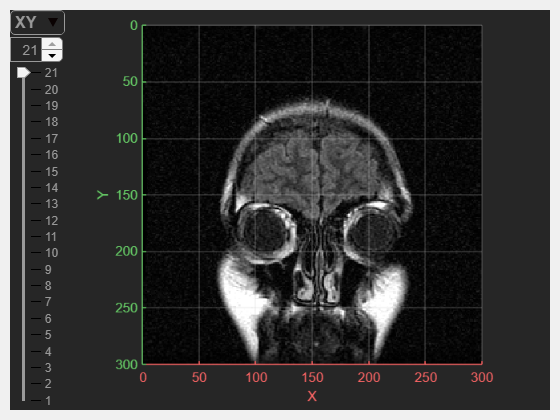

w.ShowAxes = true;
w.ShowGrid = true;

## Add Annotations

### Points Annotation

thisPoints = [
  173.7510   96.2490  146.4285
  169.3740  121.2510  146.4285
  197.4990  113.1240  146.4285
  169.3740  191.2500  146.4285
  178.7490  219.9990  146.4285
  194.3760  189.9990  146.4285
    ];

a1 = wt.model.PointsAnnotation(...
    'Name','Points a1',...
    'Points',thisPoints,...
    'Color',[0 1 0]);

w.addAnnotation(a1);

#### Line Annotation

% To add interactively:
% a = uiw.model.LineAnnotation('Color',[0 1 0])
% w.addInteractiveAnnotation(a);

thisPoints = [
  134.0250   89.6100  146.4285
  101.2980   99.7410  146.4285
   80.2590  148.0530  146.4285
   84.1560  180.0000  146.4285
  104.4150  204.9360  146.4285
  136.3650  222.0780  146.4285
    ];
    
a2 = wt.model.LineAnnotation(...
    'Name','Line a2',...
    'Points',thisPoints,...
    'Color',[1 0 0],...
    'Alpha',0.6);

w.addAnnotation(a2);

### Polygon Annotation

% To add interactively:
% a = uiw.model.PolygonAnnotation('Color',[1 1 0])
% w.addInteractiveAnnotation(a);

thisPoints = [
  200.2590  133.2480   75.0000
  180.7800  119.2200   75.0000
  181.5570   86.4930   75.0000
  175.3260   52.2090   75.0000
  129.3510   53.7660   75.0000
   82.5960   72.4680   75.0000
   56.8830  101.2980   75.0000
   40.5180  136.3650   75.0000
   46.7520  169.0920   75.0000
   52.2090  192.4680   75.0000
   67.7910  211.9470   75.0000
   98.1810  238.4430   75.0000
  148.0530  241.5570   75.0000
  176.8830  245.4540   75.0000
  188.5710  236.8830   75.0000
  194.3760  189.9990   75.0000
  213.5070  188.5710   75.0000
  219.7410  166.7520   75.0000
  222.0780  142.5960   75.0000
  215.0640  127.7910   75.0000
    ];

a3 = wt.model.PolygonAnnotation(...
    'Name','Polygon a3',...
    'Points',thisPoints,...
    'Color',[1 1 0],...
    'Alpha',0.3,...
    'IsVisible',true);

w.addAnnotation(a3);

### Mask Annotation

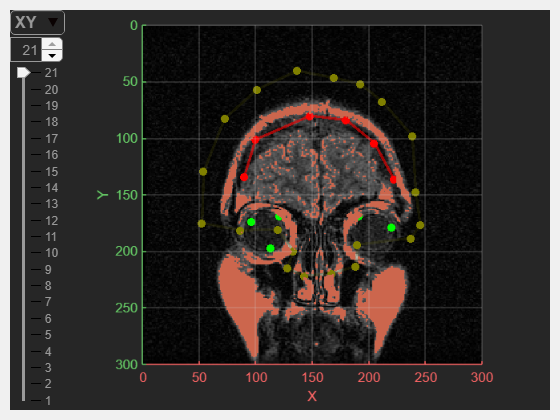

a4 = wt.model.MaskAnnotation.fromVolumeModel(volModel,...
    'Name','Mask a4',...
    'Mask',volModel.ImageData > 100,...
    'Color',[.8 .4 .3],...
    'Alpha',1);

w.addAnnotation(a4);

## Labeling Annotations Using the Mouse

You can interactively add annotations from your app. These code examples show how to implement this:

### Begin a new annotation

Add a new annotation programmatically by first creating and configuring the annotation model. Then, add it to the viewer using the widget's `addInteractiveAnnotation` method:

Add points by clicking on the surface. If you need to zoom / pan / rotate, you can enter those modes from the toolbar but turn them off again to continue adding points.

### Annotation Types

#### Point-based Annotations

There are several similar types of annotations applicable to 2D slices of an image volume.  They are defined by a set of points:

- `PointsAnnotation` - just a set of points

- `LineAnnotation` - a set of connected points

- `PolygonAnnotation` - a closed shape of connected points

While editing one of these annotation types, the mouse buttons behave this way:

- Left mouse button - add point

- Left button drag - move point

- Right mouse button - delete point

- Double-click left button - finish editing

#### Mask Annotations

Additionally, there is a `MaskAnnotation` type. This annotation is a binary mask for the 3D set of pixels in the corresponding image. 

A mask annotation must be given the same size and positioning of its corresponding volume model:

The mask can be edited using the mouse to click and drag to "paint" the mask on each individual slice. The right mouse button erases the mask. To change the brush size, you can modify the widget's current tool:

### Finishing edits

When finished making an annotation, you can finish editing it programmatically using:

### Removing an annotation

You can remove an annotation using:

### Editing an existing annotation

You can continue editing an existing annotation using:

*Copyright 2018-2021 The MathWorks, Inc.*